# 输入数据

wine_table = readtable('wine.csv');

featuresNames = {'Alcohol', 'Malic_acid', 'Ash', 'Alcalinity_of_ash', ...
    'Magnesium', 'Total_phenols', 'Flavanoids', 'Nonflavanoid_phenols', ...
    'Proanthocyanins', 'Color_intensity', 'Hue', ...
    'OD280OD315_of_diluted_wines', 'Proline'};
features = wine_table(:, featuresNames);
label = wine_table.Class;

# 线性判别分析

留出法验证

model = fitcdiscr(features, label, 'Holdout' , .15);
classifier = model.Trained{1};
test = model.Partition.test;
testsize = model.Partition.TestSize;
accuracy = sum(classifier.predict(features(test, :)) == label(test))/testsize;
display(accuracy)

accuracy = 0.9615

交叉验证

model = fitcdiscr(features, label, 'CrossVal', 'on');
accuracy = 1 - model.kfoldLoss;
display(accuracy)

accuracy = 0.9944

# 决策树分类

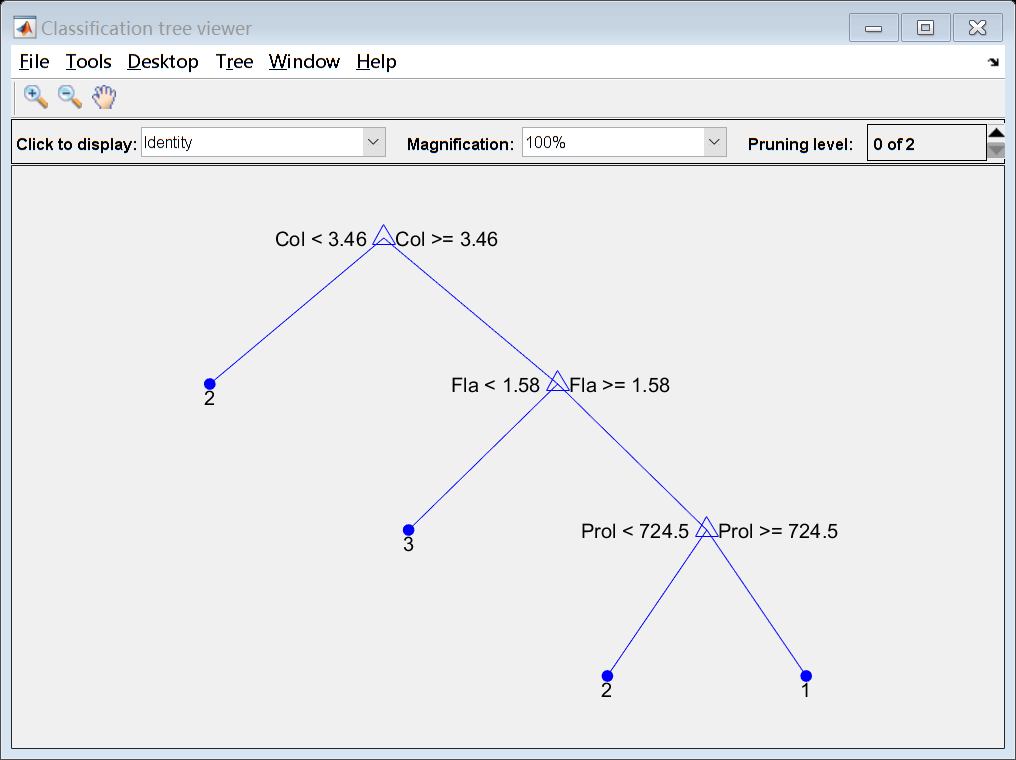

features.Properties.VariableNames = {'Alco', 'Mali', 'Ash', 'Alca', ...
    'Mag', 'Tot', 'Fla', 'Nonf', 'Proa', 'Col', 'Hue', 'OD2', 'Prol'};
tree = fitctree(features, label, 'KFold', 10, 'MinLeafSize', 5);
view(tree.Trained{1}, 'mode', 'graph')

tree.Trained{1}.NodeSize(tree.Trained{1}.IsBranchNode)    % 分支点的实例数
tree.Trained{1}.NodeSize(~tree.Trained{1}.IsBranchNode)   % 叶子节点的实例数
tree.Trained{1}.NodeError(~tree.Trained{1}.IsBranchNode)  % 叶子节点错误率
accuracy = 1 - tree.kfoldLoss

看看结点变量的区分度

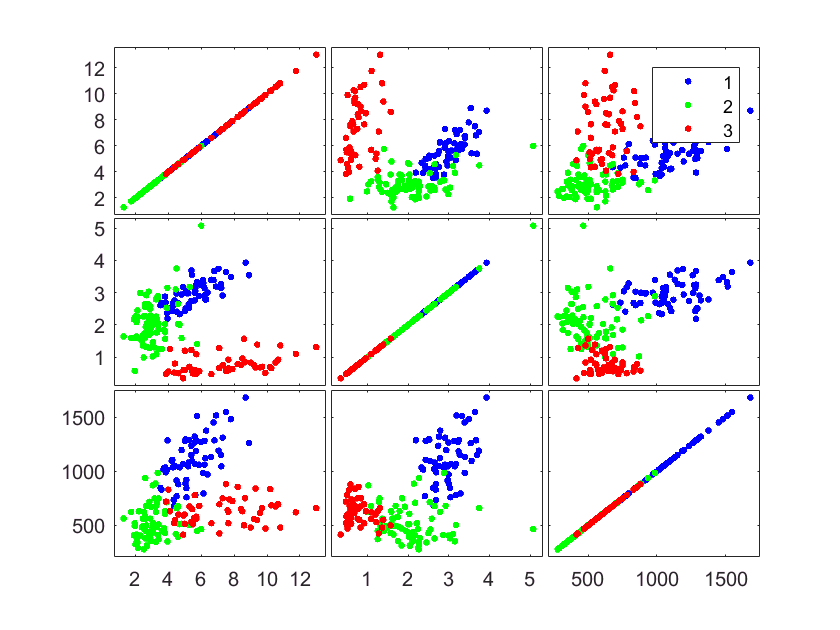

featuresNames = {'Color_intensity', 'Flavanoids', 'Proline'};
arrFeat = table2array(features(:, featuresNames));
gplotmatrix(arrFeat,arrFeat,label)